clear
load("ConvolutionArray.mat")

data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
packet_bits = GenerateBits(data_binary);

generateAmount = 100; %PER STEP!
minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 10;

allEnergies = zeros(ConvolutionEnum.last, generateAmount * stepCount);
allPoints = zeros(ConvolutionEnum.last, generateAmount * stepCount);

for amplitudeIndex = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (amplitudeIndex-1);
    for generatedIndex = 1:generateAmount
        [idealSignal, ~, ~, ADCsignal, ~] = GenerateSignal(packet_bits, generatedAmplitude);
        %Iterate thru convolution type
        for convIndex = 1:uint32(ConvolutionEnum.last)
            [currentConvolution, ~] = GenerateConvFromType(convTypes(convIndex).diffAmount, ADCsignal, ...
                convTypes(convIndex).convPreambule);
            allPoints(convIndex, (amplitudeIndex-1) * generateAmount + generatedIndex) = currentConvolution(convTypes(convIndex).expectedMaximum);
            windowSize = length(convTypes(convIndex).convPreambule);
            allEnergyTemp = GenerateEnergy(ADCsignal, length(convTypes(convIndex).convPreambule), -99999999999999999999999);
            allEnergies(convIndex, (amplitudeIndex-1) * generateAmount + generatedIndex) = allEnergyTemp(convTypes(convIndex).expectedMaximum);
        end
    end
end

meanEnergies = zeros(ConvolutionEnum.last, stepCount);
meanPoints = zeros(ConvolutionEnum.last, stepCount);
lowerQuantilePoints = zeros(ConvolutionEnum.last, stepCount);
higherQuantilePoints = zeros(ConvolutionEnum.last, stepCount);
for amplitudeIndex = 1:stepCount
    for convIndex = 1:uint32(ConvolutionEnum.last)
        maxPoint = (amplitudeIndex)*generateAmount;
        minPoint = (amplitudeIndex-1)*generateAmount + 1 ;
        meanEnergies(convIndex, amplitudeIndex) = mean(allEnergies(convIndex, minPoint : maxPoint));
        meanPoints(convIndex, amplitudeIndex) = mean(allPoints(convIndex, minPoint : maxPoint));
        lowerQuantilePoints(convIndex, amplitudeIndex) = quantile(allPoints(convIndex, minPoint : maxPoint), 0.25);
        higherQuantilePoints(convIndex, amplitudeIndex) = quantile(allPoints(convIndex, minPoint : maxPoint), 0.75);
    end
end

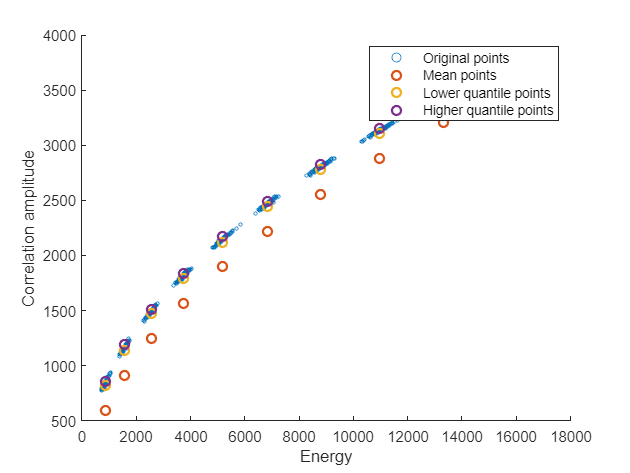

showIndex = ConvolutionEnum.basic;
figure
scatter(allEnergies(showIndex, :), allPoints(showIndex, :),5, 'DisplayName', "Original points")
hold on
scatter(meanEnergies(showIndex, :), meanPoints(showIndex, :),  'DisplayName', "Mean points", 'LineWidth',1.5)
scatter(meanEnergies(showIndex, :), lowerQuantilePoints(showIndex, :),  'DisplayName', "Lower quantile points", 'LineWidth',1.5)
scatter(meanEnergies(showIndex, :), higherQuantilePoints(showIndex, :),  'DisplayName', "Higher quantile points", 'LineWidth',1.5)
hold off
xlabel("Energy")
ylabel("Correlation amplitude")
legend

range = 1 : 2 : generateAmount;

figure
hold on
for i = 1:uint32(ConvolutionEnum.last)
    fprintf(convTypes(i).name + " correlation coef: ")
    curr_corr_coef = corrcoef(allEnergies(i, range), allPoints(i, range));
    curr_corr_coef(2, 1)
    scatter(allEnergies(i, range), allPoints(i, range), 'DisplayName', convTypes(i).name)
end

basic correlation coef: 

ans = 0.9632

negative correlation coef: 

ans = 0.4182

negative normalized correlation coef: 

ans = 0.5885

exteded correlation coef: 

ans = 0.0859

extended normalized correlation coef: 

ans = 0.6058

differentiated correlation coef: 

ans = 0.5049

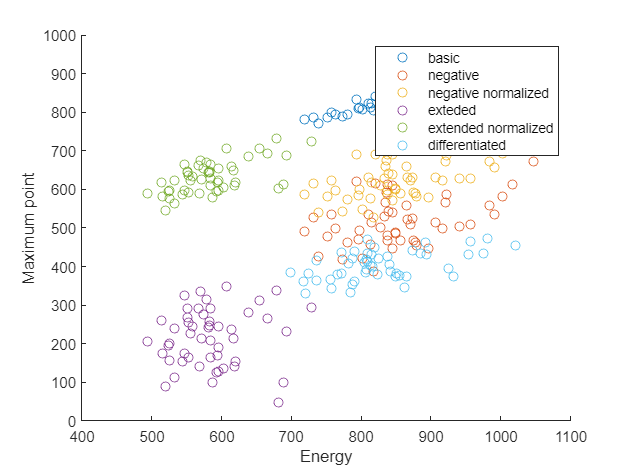

legend
xlabel("Energy")
ylabel("Maximum point")
hold off

allApproximations = ApproximationType.empty(ApproximationEnum.last, 0);
fitPower = 2;
for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        switch(approxIndex)
            case ApproximationEnum.mean
                name = "mean";
                coefficients = polyfit(meanEnergies(convIndex, :), meanPoints(convIndex, :), fitPower);
            case ApproximationEnum.minQuantile
                name = "min quantile";
                coefficients = polyfit(meanEnergies(convIndex, :), lowerQuantilePoints(convIndex, :), fitPower);
            case ApproximationEnum.maxQuantile
                name = "max quantile";
                coefficients = polyfit(meanEnergies(convIndex, :), higherQuantilePoints(convIndex, :), fitPower);
        end
        allApproximations((convIndex-1) * uint32(ApproximationEnum.last) + approxIndex) = ApproximationType(name, coefficients);
    end
end

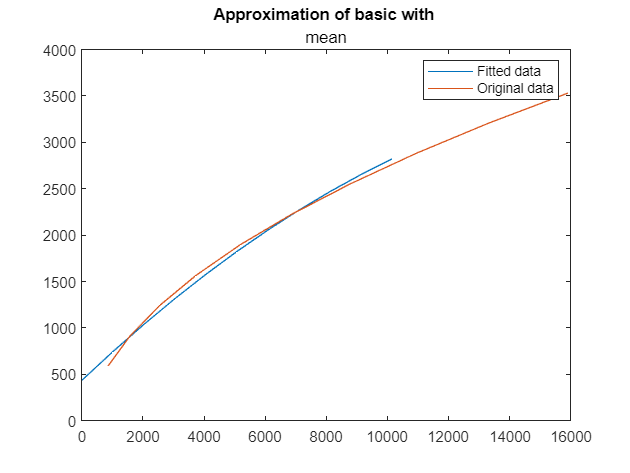

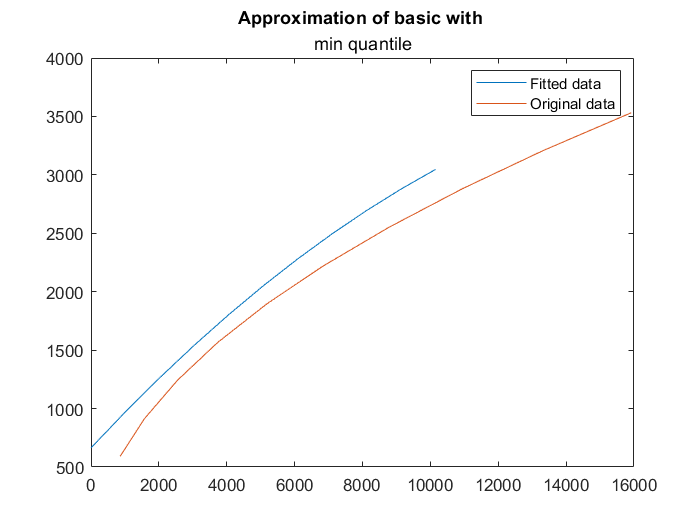

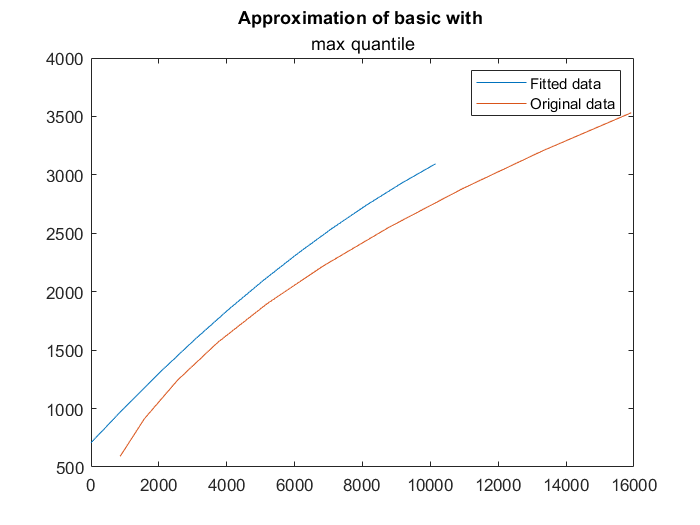

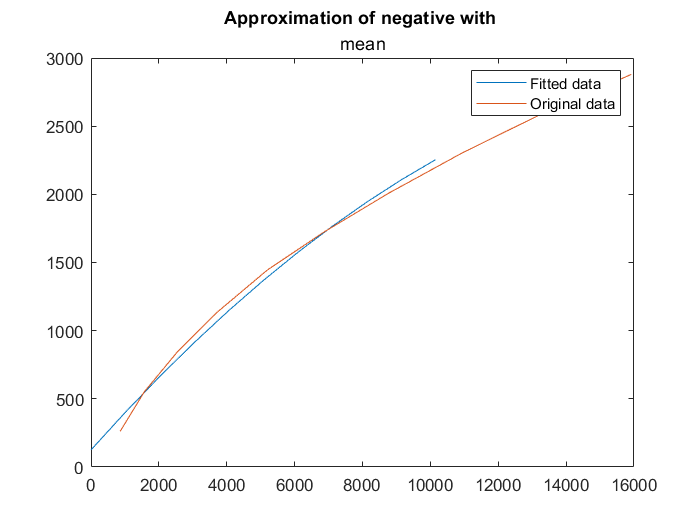

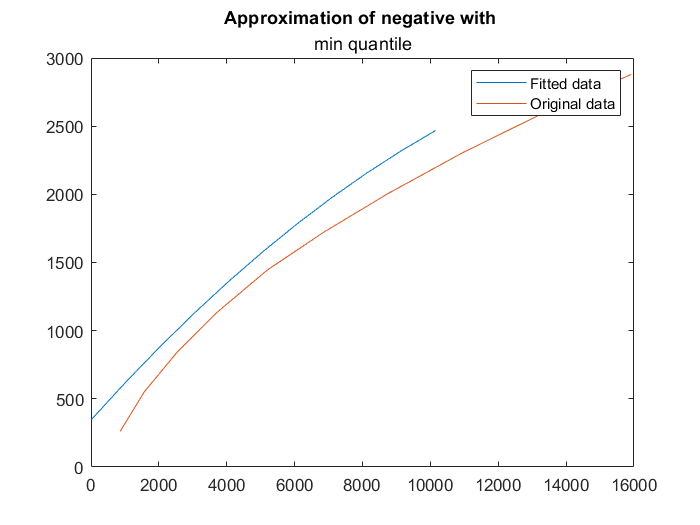

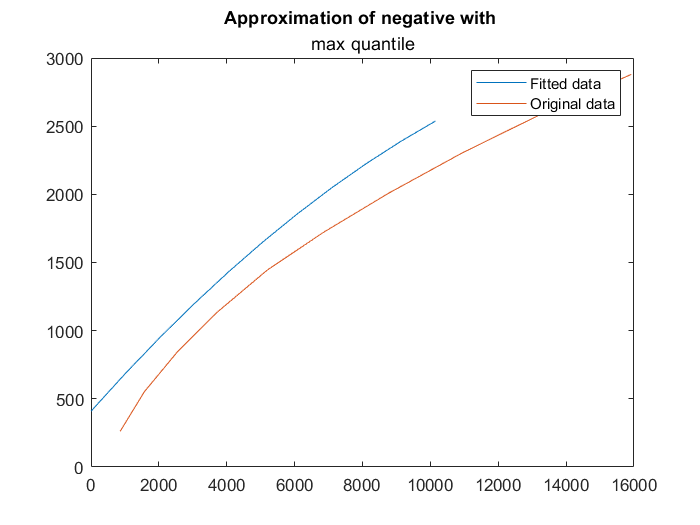

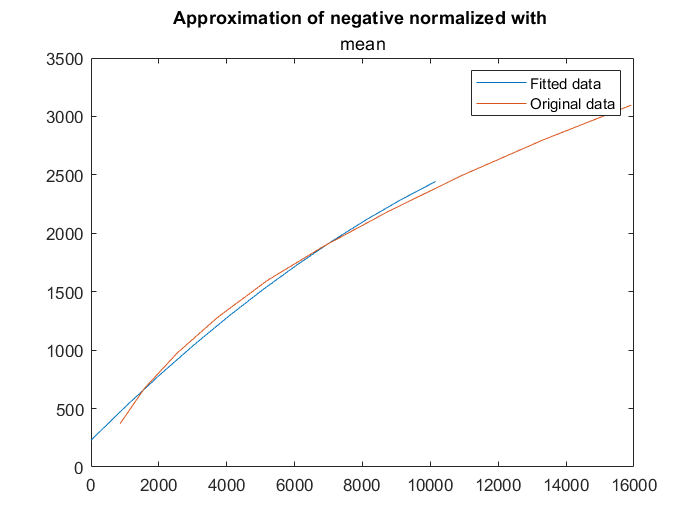

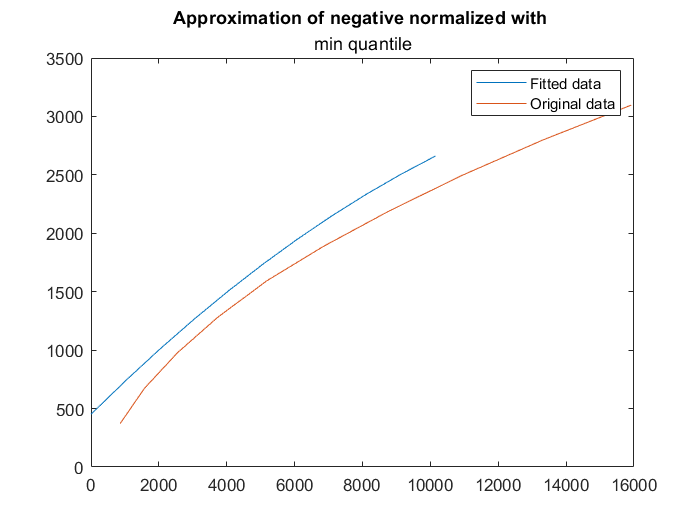

for convIndex = 1:uint32(ConvolutionEnum.last)
    for approxIndex = 1:uint32(ApproximationEnum.last)
        p_fit_x = 0:max(meanEnergies(4, :)/10):max(meanEnergies(4, :));
        p_fit = polyval(allApproximations((convIndex-1) * uint32(ApproximationEnum.last) + approxIndex).coeficients, p_fit_x);
        figure
        plot(p_fit_x, p_fit, 'DisplayName', "Fitted data")
        hold on
        plot(meanEnergies(convIndex, :), meanPoints(convIndex, :), 'DisplayName', "Original data")
        hold off
        title(sprintf("Approximation of %s with %s", convTypes(convIndex).name), allApproximations((convIndex-1) * uint32(ApproximationEnum.last) + approxIndex).name)
        legend
    end
end

save("tempNeigiamasRodiklisData.mat", "allApproximations", "convTypes")